# Estimating the Continental Geotherm

clear, close all, clc
set_demo_defaults()

(Discussion from [Geodynamics](https://www.cambridge.org/us/academic/subjects/earth-and-environmental-science/structural-geology-tectonics-and-geodynamics/geodynamics-3rd-edition?format=PB&isbn=9780521186230) by Turcotte and Schubert)

Our first example problem in heat condution is estimating the continental geotherm from available measurements. The crust is the outer layer of the Earth that over lies the Earth mantle which comprised the bulk of the Earth. Both mantle and crust of the Earth are solid but have different composition. The Earth curst has fromed from the mantle by partial melting and is enriched in radioactive elements. We distinguish the **oceanic crust** (60%) and the **continental crust** (40%). 

## Heat production in the continental crust

Today we will consider the temperature, heat flow and heat continental crust. Below are typical paramter values for the continental crust:

qs = 65e-3;   % ave. surface heat flow [W/m^2]
rho = 2700;   % ave. crustal density [kg/m^3]
H0 = 9.6e-10; % heat production near surface [W/kg]
h = 35e3;     % ave. depth of crust [m]
kappa = 3.35; % thermal conductivity [W/(m K)]

In the absence of any heat flow from the mantle into the base of the crust, the steady surface heat flow must be the integral over the heat production in the crust and hence given by


$$q_s = \int_0^h \rho H_0 \,\mathrm{d}z = \rho H_0 h$$


the obtained value of 90.72 mW/m$^2$ is 40% higher than the observed surface heat flux.

qs_estimate = rho*H0*h

qs_estimate = 0.0907

Given that crustal density and thickness are reasonably well constrained, this suggests that the heat production in surface rocks, $H_0$, is not representative. Hence it is often assumed that heat production declines exponentially with depth as


$$H = H_0 e^{-z/h_r}$$
 

where $H_0$ is the surface heat production, $h_r$is a decay depth and $z$ is the depth below the surface. Hence, the steady heat equation for the continental geotherm is given

$-\kappa \frac{\mathrm{d}^2 T}{\mathrm{d}z^2} = \rho H_0 e^{-z/h_r}$ on $z \in \left[0,\, h\right]$

with the boundary conditions: $T(z=0) = 0\, ^{\circ}\mathrm{C}$ and $\left.\kappa \frac{\mathrm{d}T}{\mathrm{d}z}\right|_{z=h} = -q_m$

Here $q_m$ is the mantle heat flow into the base of the crust. The surface heat flow is the sum of the mantle heat flow and the heat produced in the crust and given by

$q_s = q_m +h_r  \rho H_0$.       (note here $q_m$ and $q_s$ are assumed to be positive)

The two unknown quantities $q_m$ and $h_r$can be determined from the observed variation of the surface heat flow with surface heat productivity as shown in the Figure. 

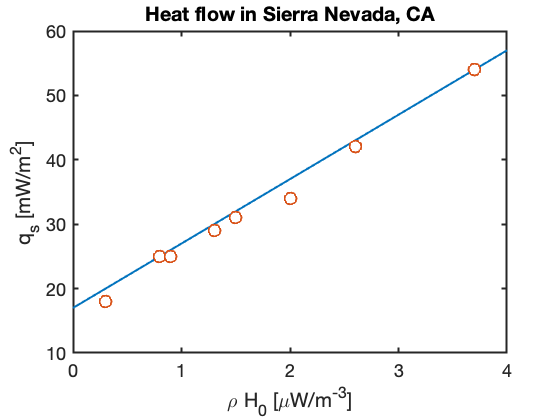

load SierraNevadaData.mat
x = linspace(0,4,10);
plot(x,17+10*x,'-'), hold on
plot(rhoH0,q0,'o','markerfacecolor','w')
xlabel('\rho H_0 [\muW/m^{-3}]')
ylabel('q_s [mW/m^2]')
title('Heat flow in Sierra Nevada, CA')

Here the slope of the data give $h_r=10\,\mathrm{km}$ and the intercept $q_m=17\,\mathrm{mW/m}^2$. This suggests that between 5.5% and 68.5% of the surface heat flow is due to radiogenic heat production in the crust.

[min((q0-17)./q0*100) max((q0-17)./q0*100)]

ans =     5.5556   68.5185


## Computing the continental geotherm

Integrating the boundary value twice and using the BC's to eliminated the tow coefficients we obtain the following expression for the continental geotherm and heat flow.


$$T = T_0+\left(\frac{q_m}{\kappa}-\frac{\rho H_0h_r}{k}e^{-h/h_r}\right)z+\frac{\rho H_0 h_r^2}{k}(1-e^{-z/h_r})$$



$$q=-q_m-\rho H_0h_r \left(e^{-z/h_r}-e^{-h/h_r}\right)$$


where $T_0$ is the surface temperature. Note here $q_m$ and $q_s$ are assumed to be positive. A plot of the typical geotherm is shown on the right.

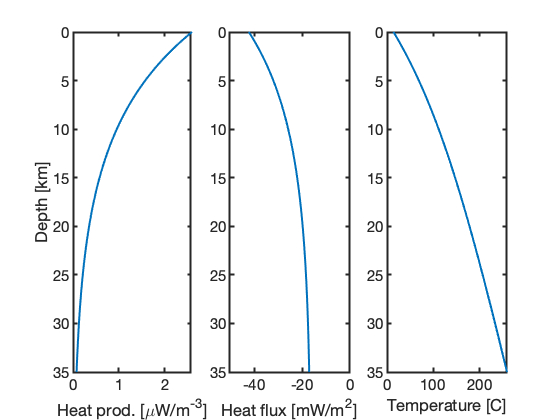

T0 = 14;
hr = 10e3;
qm = 17e-3; 
q = @(z) -qm-rho*H0*hr*(exp(-z/hr)-exp(-h/hr));
T = @(z) T0 + (qm/kappa-rho*H0*hr/kappa*exp(-h/hr))*z + rho*H0*hr^2/kappa*(1-exp(-z/hr));
zplot = linspace(0,h,100);
figure(1)
subplot 131
plot(rho*H0*exp(-zplot/hr)*1e6,zplot/1e3),hold on
set(gca, 'YDir','reverse')
xlabel('Heat prod. [\muW/m^{-3}]')
ylabel('Depth [km]')

subplot 132
plot(q(zplot)*1e3,zplot/1e3), hold on
set(gca, 'YDir','reverse')
xlabel('Heat flux [mW/m^2]')
xlim([-50 0])
% ylabel('Depth [km]')

subplot 133
plot(T(zplot),zplot/1e3), hold on

set(gca, 'YDir','reverse')
xlabel('Temperature [C]')

% ylabel('Depth [km]')


## Numerical solution

Here we use the functions we will build in class to solve for the continental geotherm numerically.

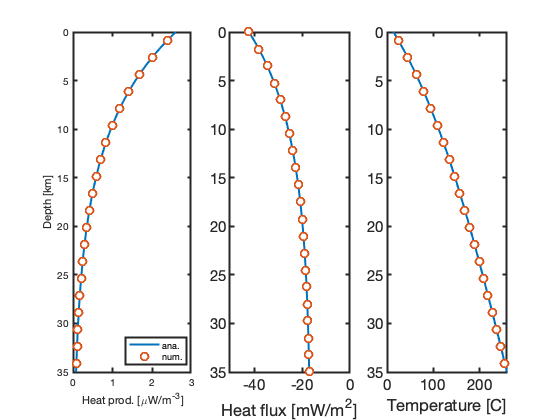

% 0) Note we have already defined all physical constants above
% 1) Define the domain and create the grid
Grid.xmin = 0; Grid.xmax = h; Grid.Nx = 20; % Note: here x is the depth
Grid = build_grid(Grid);
% 2) Build operators and r.h.s.
[D,G,I] = build_ops(Grid);
L = -D*kappa*G;
fs = rho*H0*exp(-Grid.xc/hr);
% 3) Define location and value of BC's
BC.dof_dir   = Grid.dof_xmin;   % Dirichlet BC at x = 0
BC.dof_f_dir = Grid.dof_f_xmin;
BC.g         = T(Grid.dx/2);    % Using analytic solution to set BC in cell center
BC.dof_neu   = Grid.dof_xmax;   % Neuman BC at x = h
BC.dof_f_neu = Grid.dof_f_xmax;
BC.qb        = qm;             % Mantle heat flow (positve, i.e. into the crust)
[B,N,fn] = build_bnd(BC,Grid,I);
% 4) Solve BVP and compute the heat flux
Tnum = solve_lbvp(L,fs+fn,B,BC.g,N);
qnum = comp_flux(D,kappa,G,Tnum,fs,Grid,BC);

figure(1)
subplot 131
plot(fs*1e6,Grid.xc/1e3,'o','markerfacecolor','w','markersize',8)
legend('ana.','num.','location','southeast')
subplot 132
plot(qnum*1e3,Grid.xf/1e3,'o','markerfacecolor','w','markersize',8)

subplot 133
plot(Tnum,Grid.xc/1e3,'o','markerfacecolor','w','markersize',8)